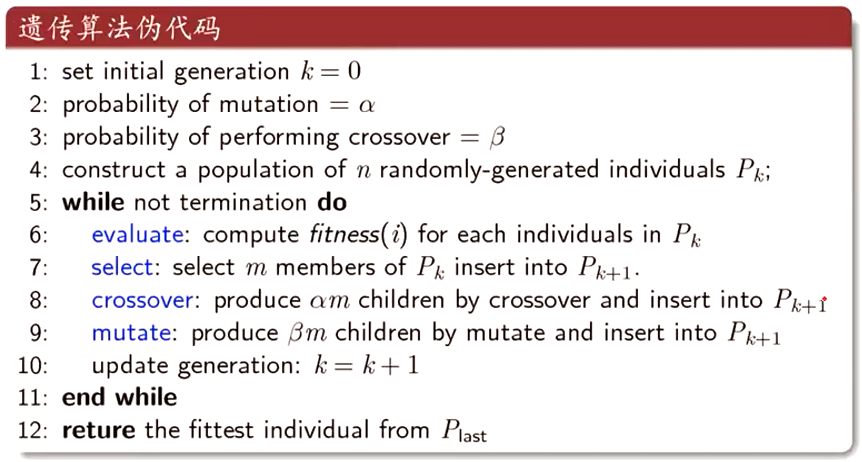

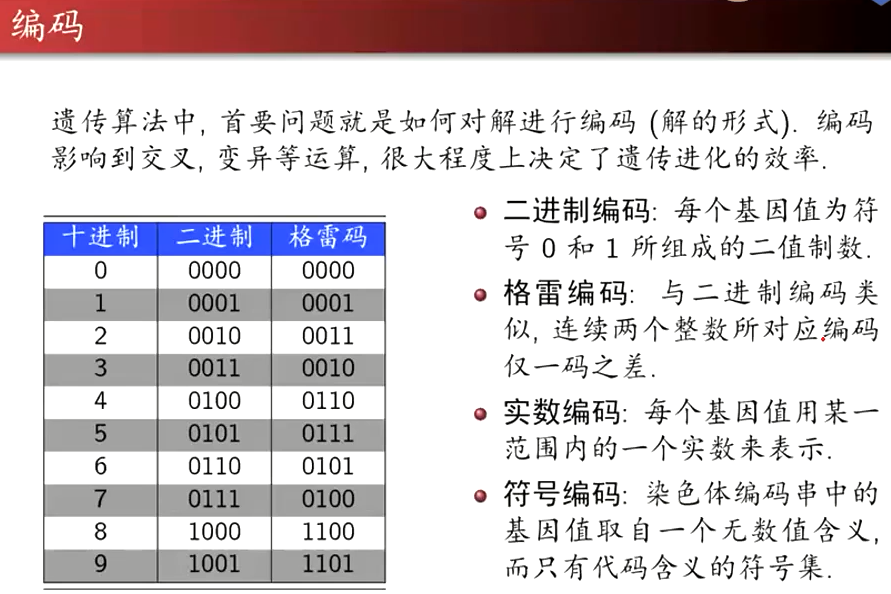

popSize=100;
max_generation=1000;
Pmutation=0.16;
numberofcities=34;
for i=popSize
    pop(i,:)=randperm(numberofcities);
end

for i=1:max_generation
    fitness=1/totaldistance(pop,dis);
    [maxfit,bestID]=max(fitness);
    bestPop=pop(bestID,:);
    pop=select(pop,fitness,popSize,'competition');
    pop=crossover(pop);
    pop=mutation(pop,Pmutation);
    pop=[bestPop;pop];
end

Unrecognized function or variable 'dis'.

popDist=total_distance(pop,dis);
[minDist,index]=min(popDist);
optRoute=pop(index,:);